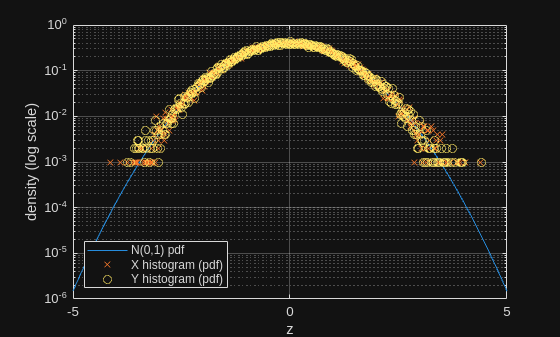

dataX = readmatrix('histogram_X.txt');  
dataY = readmatrix('histogram_Y.txt');

bx = dataX(:,1); fx_counts = dataX(:,2);
by = dataY(:,1); fy_counts = dataY(:,2);


binw = bx(2) - bx(1);          
Nx   = sum(fx_counts);          
Ny   = sum(fy_counts);          
fx_pdf = fx_counts / (Nx * binw);
fy_pdf = fy_counts / (Ny * binw);

% Theoretical standard normal pdf
z  = -5:0.001:5;
fz = exp(-0.5*z.^2) / sqrt(2*pi);

% Log-scale overlay (your original intention with semilogy)
figure;
semilogy(z, fz, '-', bx, fx_pdf, 'x', by, fy_pdf, 'o'); grid on;
xlabel('z'); ylabel('density (log scale)');
legend('N(0,1) pdf','X histogram (pdf)','Y histogram (pdf)','Location','SouthWest');
xlim([-5 5]);